# Expand Example 2.13:

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

A second order system is described by the difference equation


$$y[n]-1.4\,y[n-1]+0.85\,y[n-2] = 0$$


Its natural response is in the form


$$y_{h}[n] =
d_{1}\,(0.922)^{n}\,\cos(0.7086\,n) +
d_{2}\,(0.922)^{n}\,\sin(0.7086\,n)$$
 

for $n\ge 0$.  Imposing the initial conditions for $n=-1$ and $n=-2$ yields


$$\begin{array}{r l}
y_{h}[-1] &=0.8235\,d_{1}-0.7058\,d_{2} \\
y_{h}[-2] &=0.1800\,d_{1}-1.1625\,d_{2}
\end{array}
$$


ym1 =5; % Enter y[-1]
ym2 =7; % Enter y[-2]
%
n = [-2:49];    % Vector of sample indices
% Compute the natural response
r1 = 0.922;         
omega1 = 0.7086;
A = [0.8235,-0.7058;0.1800,-1.1625];
%A = [0.6923,-0.5385;0.1893,-0.7456];
B = [ym1;ym2];
D = A\B

D =     1.0501
   -5.8589


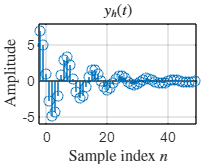

n = [-2:49];   % Vector of sample indices
% Compute the natural response
yh = D(1)*(r1.^n).*cos(omega1*n)+D(2)*(r1.^n).*sin(omega1*n);
% Graph the natural response
stem(n,yh); grid;
axis([-2.5,49.5,-6,8]);
set(0,'defaultTextInterpreter','latex');
title('$y_h(t)$');
xlabel('Sample index $n$');
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex');